# 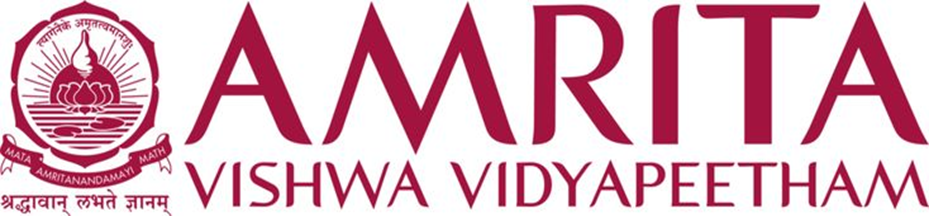

# 22MAT122 - MATHEMATICS FOR COMPUTING - 2

# DEEP CONVOLUTION TABLE : DEEP LEARNING WITHOUT CONVOLUTIONS

#### **Done by :**

Abdul Azhar - CB.SC.U4AIE24301

Deepak Prabhu - CB.SC.U4AIE24312

Pranesh.M - CB.SC.U4AIE24345

Sandhiya.D - CB.SC.U4AIE24353

## Step 1: Load CIFAR-10 Dataset

This CT model uses the dataset CIFAR-10 which has 60,000 32x32 colour images in 10 classes, with 6000 images per class. There are 50000 training images and 10000 test images.

- Each image is 32×32 pixels with 3 color channels (RGB).

- `Categorical()` is required because the training function expects class labels in that format. 

% The CIFAR-10 dataset consists of 60,000 color images (32x32 pixels) in 10 classes.
% We split this into 50,000 training images and 10,000 test images.

% Datasetdisp('Loading CIFAR-10 dataset...');
clc; clear; close all;
data_path = 'C:\Users\sandh\OneDrive\Desktop\projects-sem 2\EOC+MFC\data\cifar-10-batches-mat\';

[trainImages, trainLabels, testImages, testLabels] = loadCIFAR10Data(data_path);

if isempty(trainImages) || isempty(testImages)
    error('Failed to load CIFAR-10 data. Check data path or file integrity.');
end

## Step 2: Preprocessing

We are normalizing the values because the neural network converges faster when the input values are normalised.

% Normalize images by scaling RGB values from [0, 255] → [0, 1]
% Subtract mean image for zero-centering

fprintf('Step 2: Preprocessing data...\n');

Step 2: Preprocessing data...


trainImages = im2double(trainImages);
testImages = im2double(testImages);

% Calculate mean of training images to normalize both train and test sets

meanImage = mean(trainImages, 4);
trainImages = trainImages - meanImage;
testImages = testImages - meanImage;

% Convert labels to categorical format for training

trainLabels = categorical(trainLabels);
testLabels = categorical(testLabels);

## Step 3: Data Augmentation

We use techniques like random rotation, horizontal flipping, scaling and translation to  increase the diversity of training images. This helps the model generalize better by making it more robust to many variations.

% Helps improve generalization by introducing image variations like:
% - Random rotation
% - Horizontal flipping
% - Scaling and translation
% It also prevents data overfitting

fprintf('Step 3: Creating augmented datastore...\n');

Step 3: Creating augmented datastore...


imageSize = [32 32 3];

augmenter = imageDataAugmenter( ...
    'RandRotation', [-10, 10], ...
    'RandXTranslation', [-3 3], ...
    'RandYTranslation', [-3 3], ...
    'RandXReflection', true);

augimdsTrain = augmentedImageDatastore(imageSize, trainImages, trainLabels, 'DataAugmentation', augmenter);
augimdsTest = augmentedImageDatastore(imageSize, testImages, testLabels);

## Step 4: Load Pretrained ResNet-18 and Modify

ResNet-18 is pretrained on ImageNet (224 x 224 images, 1000 classes)


$$T^{\text{in}} \in \mathbb{R}^{H_i \times W_i \times D_i}$$


% We use 224 x 224 as input because ResNet-18 expects images of the particular size as input. Also, we add new layers for 10-class classification (CIFAR-10).

fprintf('Step 4: Loading and modifying ResNet-18...\n');

Step 4: Loading and modifying ResNet-18...


net = resnet18;
lgraph = layerGraph(net);

% Modify the input size to match CIFAR-10's input size
lgraph = replaceLayer(lgraph, 'data', imageInputLayer([32 32 3], 'Name', 'input', 'Normalization', 'none'));

% Replace final layers for 10-class classification
numClasses = 10;
lgraph = replaceLayer(lgraph, 'fc1000', fullyConnectedLayer(numClasses, 'Name', 'fc10'));
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', classificationLayer('Name', 'output'));


## Step 5: Training Options

**SGDM (Stochastic Gradient Descent with Momentum)** is used again.

**Learning Rate Schedule**: piecewise drops the learning rate by DropFactor after DropPeriod epochs.

α_new = α_old × DropFactor

(eg. 0.01 --> 0.001 after 30 epochs)

The training runs on CPU.

-> We use the Stochastic Gradient Descent method  in the convolution tables method with momentum to help avoid the local minima by :


$$ $v_t = \mu v_{t-1} - \eta \nabla L(\theta)$$$



$$$\theta = \theta + v_t$$$


where μ is the momentum and η is the learning rate.


fprintf('Step 5: Setting training options...\n');

Step 5: Setting training options...


options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsTest, ...
    'ValidationFrequency', 100, ...
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'cpu', ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 30);


## Step 6: Train the Model

Backpropagation runs here to minimize the loss.

Training uses the specified options, including learning rate schedule and data augmentation.

fprintf('Step 6: Training ResNet-18...\n');

Step 6: Training ResNet-18...


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:02:08 |       10.16% |       14.43% |       3.7786 |       3.2924 |          0.0100 |
|       1 |          50 |       00:04:22 |       44.53% |              |       1.6565 |              |          0.0100 |
|       1 |         100 |       00:08:14 |       59.38% |       61.60% |       1.2308 |       1.1078 |          0.0100 |
|       1 |         150 |       00:10:20 |       61.72% |              |       1.0530 |              |          0.0100 |
|       1 |         200 |       

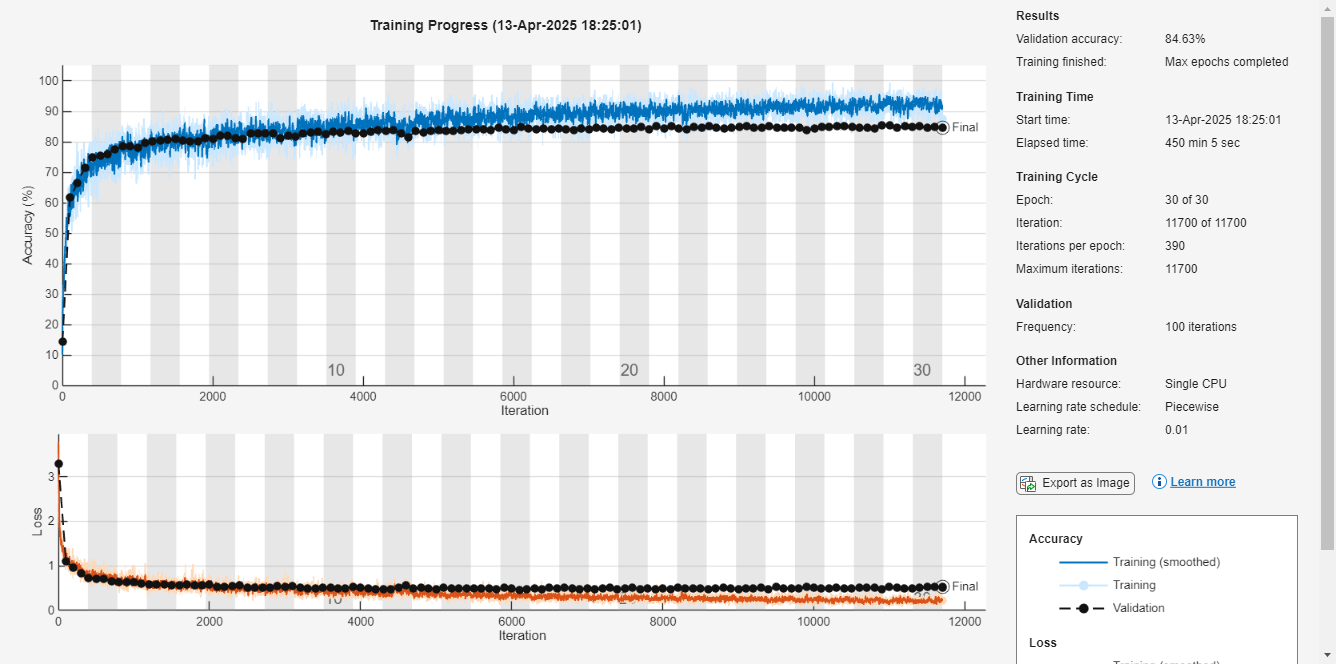

net = trainNetwork(augimdsTrain, lgraph, options);

## Step 7: Evaluate the Model

The **confusion matrix** shows how well the model predicts each class by comparing predicted vs actual labels.  Each row represents actual classes, and each column shows predicted ones and the diagonal values indicate correct predictions, while off-diagonal values show misclassifications.

fprintf('Step 7: Evaluating test data...\n');

Step 7: Evaluating test data...


predictedLabels = classify(net, augimdsTest);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 84.63%


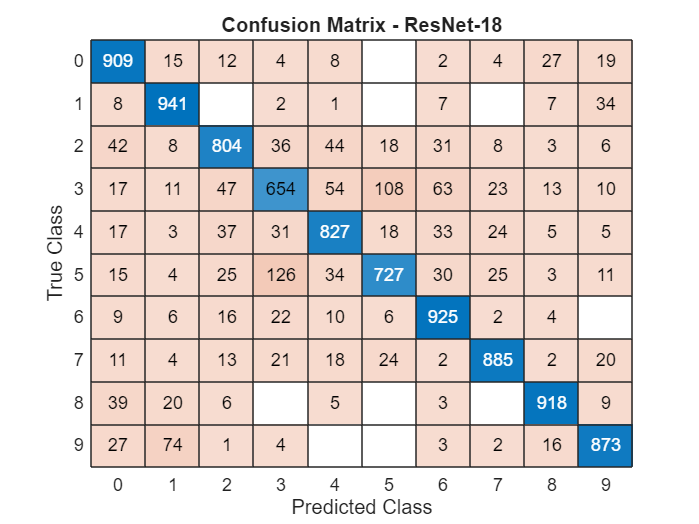


figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix - ResNet-18');

## Step 8: Save the Accuracy

fprintf('Saving Accuracy...\n');

Saving Accuracy...


fid = fopen('resnet_accuracy_matlab.txt', 'w');
fprintf(fid, 'ResNet-18 Accuracy: %.2f%%\n', accuracy * 100);
fclose(fid);

fprintf('\n================= ResNet-18 Program Completed =================\n');


================= ResNet-18 Program Completed =================



%% Helper Function (Unchanged)
function [trainImgs, trainLbls, testImgs, testLbls] = loadCIFAR10Data(dataPath)
    trainImgs = [];
    trainLbls = [];
    for i = 1:5
        batch = load(fullfile(dataPath, sprintf('data_batch_%d.mat', i)));
        imgs = reshape(batch.data', 32, 32, 3, []);
        imgs = permute(imgs, [2 1 3 4]);
        trainImgs = cat(4, trainImgs, imgs);
        trainLbls = [trainLbls; batch.labels];
    end
    testBatch = load(fullfile(dataPath, 'test_batch.mat'));
    testImgs = reshape(testBatch.data', 32, 32, 3, []);
    testImgs = permute(testImgs, [2 1 3 4]);
    testLbls = testBatch.labels;
end

% This live script demonstrates how deep learning using convolutional tables (CTs) can be evaluated using a modified ResNet18 on CIFAR-10.
% The core idea is to use pretrained convolution layers and replace the
% dense layers with custom ones.
% This approach is also compatible with fewer resources.
